### NDVI POR AÑO del año 2000 al 2022

### 1.- Inicialización de la información

Imports y declaración de variables

import matlab.io.hdfeos.*

clearvars -except area_estudio;
close all;

Declaracón de variables como directorio de datos, latitud y longitud del área de estudio y posición en las cuadriculas de MODIS. 

declaraciones

>>> Declarando variables...ok



% Los años que se desean consultar
anios = 2000:2022;

Variables para realizar seguimiento del código y mostrar más mensajes y/o mapas. Tiempo de pausa en segundos.

debug_pausa = 2; %tiempo de pausa de imagenes
debug_dibujar_mapa = false;  %dibujar los mapas 

Leer todos los archivos de la zona de estudio y guardar la información en una tabla

| idx | diaj | dia | mes | estación | año | v6 | v7 | calidad |

%% obtener la info del área de estudio
[lat,lon,ndvi] = m_leer_dir_hdfs(dir_data,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos


info_hdf = m_infohdfs2table(dir_data);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos


Matriz que delimita el área de estudio. Se carga de archivo "area_estudio.mat". Sino existe. Lo crea. El proceso puede tardar un rato

ae = exist("area_estudio","var");
if ae == 0
    ae = exist("area_estudio.mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load area_estudio;
    else
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
        
    end
else
    if( numel(area_estudio) <= 1)
        disp("La variable area_estudio sera sustituida");
        area_estudio = m_crear_area_estudio(dir_data+'KML\RH26.kml',lat,lon);
    end
end

>>> Cargando área de estudio


Pixeles en total del área de estudio

calidad_total = sum(area_estudio,"all");

Dibujar mapa de prueba de lectura de datos

% if debug_dibujar_mapa == true
%     ndvi(area_estudio==false)=NaN;
%     m_dibujar_mapa(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI TEST",[],ndvi_colormap,"NDVI");
%     m_dibujar_kml(dir_data,"RH26",1,'b',"RH26")
%     pause(debug_pausa);
% end 

### 2.- Declarar variables para obtener la información por año



% Arreglo donde se almacenara el promedio de NDVI por año
tabla_promedio_anios =zeros(1,length(anios));
tabla_desvEst_anios =zeros(1,length(anios));

% Arreglo en 3d
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,length(anios));


### 3.- Recuperar la información y crear las matrices de 3 dimensiones

Recuperar  la información

bp=waitbar(0,'Obteniendo información'); 

for a = 1:length(anios)
        waitbar(a/length(anios),bp);

        tmp =  find(  info_hdf.anio == anios(a)  );
        img_fechas_consulta = info_hdf(tmp,:);
        [filas,~] = size(img_fechas_consulta);
%         disp("Año: "+anios(a) +". No de archivos: "+filas);
        
        %arreglo de promedios de las imagenes
        arr_promedio_anio = zeros(1,filas);
        arr_ndvi_anio  = zeros( ndvi_tam(1),ndvi_tam(2) ,filas);
        
        % obtener la info de un año
        for i=1:filas
            %disp("Analizando "+i+" de "+filas);
            [ndvi,~,~,disponibilidad] = m_obtener_ndvi(dir_data,img_fechas_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
        
            % recortar el area de estudio
            ndvi(area_estudio==false)=NaN;
            disponibilidad(area_estudio==false)=NaN;

            %omitir las zonas con nubes o nieve
            ndvi (disponibilidad>1)=NaN;
            disponibilidad(disponibilidad>1)=NaN;
        
            calidad = m_calidad_imagen(disponibilidad,calidad_total);
        
            % promedio ndvi si es de buena calidad, sino nan
            if calidad >=95
                promedio_ndvi = mean(ndvi,'all','omitnan');
                arr_promedio_anio(i) = promedio_ndvi;
                arr_ndvi_anio(:,:,i) = ndvi;
            else
                arr_promedio_anio(i) = nan;
                arr_ndvi_anio(:,:,i) = nan;
            end
   
        end

    tabla_promedio_anios(a) = mean(arr_promedio_anio,"all","omitnan");
    tabla_desvEst_anios(a) = std(arr_promedio_anio,0,"all","omitnan");

    arr_ndvi(:,:,a) = m_mean_3dpp(arr_ndvi_anio);

    if debug_dibujar_mapa == true 
        % dibujar el mapa
        m_dibujar_mapa_ndvi(lon_proyeccion,lat_proyeccion,lon,lat,ndvi_promedio_anio,"RH 26 ("+img_fechas_consulta.anio(i)+")",1);
        m_dibujar_otras_areas(dir_data,"RH26_prom_anio_"+img_fechas_consulta.anio(i)+"-)");
        pause (debug_pausa);
        
    end
end

Año: 2000. No de archivos: 20
Año: 2001. No de archivos: 20
Año: 2002. No de archivos: 19
Año: 2003. No de archivos: 23
Año: 2004. No de archivos: 23
Año: 2005. No de archivos: 23
Año: 2006. No de archivos: 23
Año: 2007. No de archivos: 23
Año: 2008. No de archivos: 23
Año: 2009. No de archivos: 23
Año: 2010. No de archivos: 23
Año: 2011. No de archivos: 23
Año: 2012. No de archivos: 23
Año: 2013. No de archivos: 23
Año: 2014. No de archivos: 23
Año: 2015. No de archivos: 23
Año: 2016. No de archivos: 23
Año: 2017. No de archivos: 23
Año: 2018. No de archivos: 23
Año: 2019. No de archivos: 23
Año: 2020. No de archivos: 23
Año: 2021. No de archivos: 23
Año: 2022. No de archivos: 23


close(bp); 

### 4.- Usar los datos obtenidos 

Mostrar el promedio por día de NDVI 

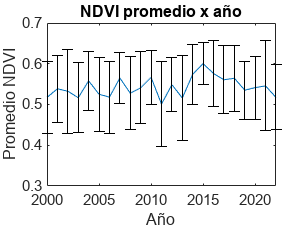

figure;

plot(anios,tabla_promedio_anios);
title('NDVI promedio x año')
xlabel('Año')
ylabel('Promedio NDVI')
xlim([anios(1) anios(end)]);
ylim([0.3 0.7]);

hold on

er=errorbar(anios,tabla_promedio_anios,tabla_desvEst_anios); 
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

exportgraphics(gca,"img/g_promedio_x_año.png",'Resolution',300) 

### 5. Mostrar el promedio de un año en particular

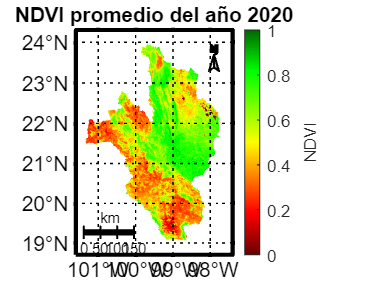

anio = 2020;

m_dibujar_mapa_ndvi(lon_mapa,lat_mapa,lon,lat,arr_ndvi(:,:,anios==anio),"NDVI promedio del año "+anio,0);
%m_dibujar_otras_areas(dir_data);

exportgraphics(gca,"img/m_promedio_x_año_"+anio+".png",'Resolution',300) 